# **LAB SESSION 10**

## **Uniform and Normal Distributions.**

**Objective:** To get familiar with Uniform and Normal Distributions and their implementation in MATLAB

**Introduction:**

    **Uniform Distribution:**

    A random variable X is said to be uniform on the interval [a,b] if its probability density function(PDF) is of the form:


$$f_{\textrm{X}} =\frac{1}{b-a}\;\;\;\;,\;a\le x\le b$$


    **Normal Distribution:**

    A continuous random variable X is said to be Normal/Gaussian on the interval [a,b] if its probability density function(PDF) is of the form:


$$f_{\textrm{X}} =\frac{1}{\sqrt{2\pi }\sigma }e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }} \;\;\;\;,0\le \sigma ,\mu$$


%%Uniform Distribution
clear all
clc

a = input('Enter the Interval START Limit/s [a]:\n     1.Scalar (e.g: 2)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n a =');
b = input('Enter the Interval END Limit/s [b]:\n     1.Scalar (e.g: 2)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n b =');
x = min([a,b])-1:0.01:max([a,b])+1;
for i = 1:length(a)
A = makedist('uniform',a(i),b(i));
P = pdf(A,x);
hold on
plot(x,P,'LineWidth',2)
end

title('Uniform Distribution')
xlabel('x (Radian)')
ylabel('fx(x)')


**TASK # 1**

**Find the Uniform Distribution for interval/s:**

- **[1,4]**

- **[0,1] , [-2,2] , [-2,1]**

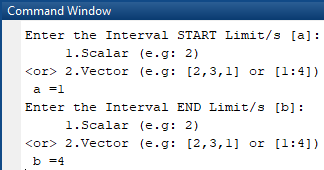

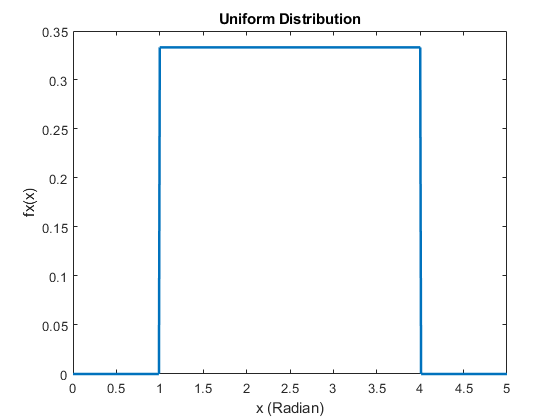

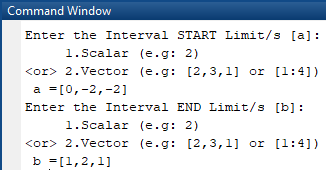

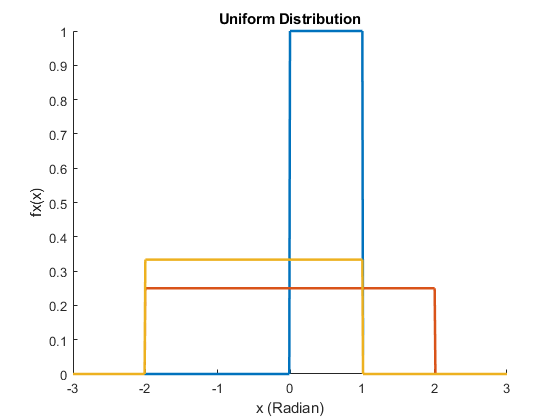

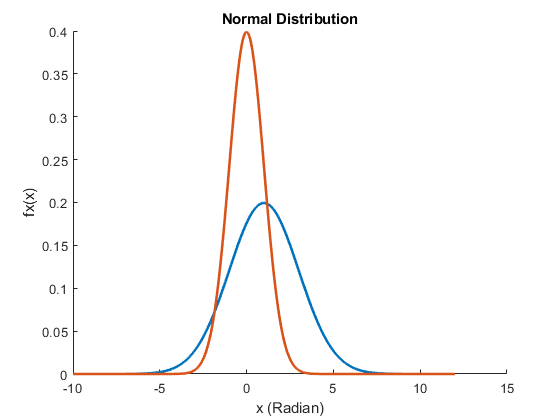

%% Normal Distribution
clear all
close all
clc

a = input('Enter the Interval START Limit/s [a]:\n     1.Scalar (e.g: 2)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n a =');
b = input('Enter the Interval END Limit/s [b]:\n     1.Scalar (e.g: 2)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n b =');
x = min([a,b])-10:0.01:max([a,b])+10;

for i = 1:length(a)
A = makedist('Normal','mu',a(i),'sigma',b(i));
P = pdf(A,x);
hold on
plot(x,P,'LineWidth',2)
end

title('Normal Distribution')
xlabel('x (Radian)')
ylabel('fx(x)')

**TASK # 2**

**Find the Normal Distribution for interval/s:**

- **[1,2]**

- **[1,2] , [0,1]**